## EBS 221 Agricultural Robotics

## Spring Quarter 2025

### **Assignment 2**

A. (45 pts). Write a Matlab function that implements a pure-pursuit controller. The function should be called in your main program every DT, and return the steering angle and cross-track error:

`[steer_angle, cross_track_error] = purePursuitController(q, L, Ld, path);`

Use the following parameters: tractor with wheelbase = 2.5 m; γmax = 45o; γmin = - γmax; v = vmax= 1 m/s; τγ = 0.0 s, τv = 0.0 s; dt=1 ms; DT=10 ms.

Initial pose [15 5 π/2]. T = 60.0 s; % maximum simulation time.

type purePursuitController.m


function [steer_angle, cross_track_error] = purePursuitController(q, L, Ld, path)
    % Extract current state
    x = q(1);
    y = q(2);
    theta = q(3);

    % Find the closest point on the path
    distances = sqrt((path(:,1) - x).^2 + (path(:,2) - y).^2);
    [~, closest_idx] = min(distances);

    % Lookahead goal point: find the first point that is at least Ld away
    goal_idx = closest_idx;
    while goal_idx < size(path,1) && norm([x y] - path(goal_idx,:)) < Ld
        goal_idx = goal_idx + 1;
    end
    
    % If end of path is reached, just use the last point
    if goal_idx >= size(path,1)
        goal_idx = size(path,1);
    end

    goal_point = path(goal_idx, :);

    % Transform goal point to vehicle coordinate frame
    dx = goal_point(1) - x;
    dy = goal_point(2) - y;
    local_x =  cos(theta)*dx + sin(theta)*dy;
    local_y = -sin(theta)*dx + cos(theta)*dy;

    % Compute curvature and steering angle
    curvature = 2 * local_y / (Ld^2);
    steer_angle = atan(L


% Parameters
L = 2.5;
Ld = 2.0;  % can be tuned
dt = 0.001;
DT = 0.01;
T = 60.0;
gamma_max = deg2rad(45);
gamma_min = -gamma_max;

% Initial pose
q = [15; 5; pi/2; 0; 1];  % [x; y; theta; gamma; v]

% Sample path (Nx2 array)
path = [linspace(15, 35, 100)' linspace(5, 25, 100)'];

% Run controller
[steer_angle, cross_track_error] = purePursuitController(q, L, Ld, path);

B. (20 pts)

- Generate points on a circle of radius 5m, centered at (9,7), using this code: a = 0: 0.1 : 2*pi; % angle step for points on circular pathx = 9 + 5*sin(a); y = 7-5*cos(a);

- Write a script that performs closed-loop path tracking to follow the circular path using a look-ahead ld= 2m. Use your robot_bike_dyn.m.

- Plot the cross-track error and the robot’s trace (the trace of the point on the robot’s frame origin).

- Why is the cross-track error nonzero, whereas the robot path looks good? How can you improve the cross-track error calculation?

% 
clear; clc;

type robot_bike_dyn.m


function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)
    global dt; 
    global DT;

    % Extract current state
    x     = q(1);
    y     = q(2);
    theta = q(3);
    gamma = q(4);
    v     = q(5);

    % Desired inputs
    gamma_d = u(1);  % desired steering angle
    v_d     = u(2);  % desired velocity

    % Saturate desired inputs
    gamma_d = max(min(gamma_d, umax(1)), umin(1));
    v_d     = max(min(v_d, umax(2)), umin(2));

    % First-order dynamics for steering and velocity
    dgamma = (gamma_d - gamma) / tau_gamma;
    dv     = (v_d - v) / tau_v;

    % Euler integration to update gamma and v
    gamma = gamma + dt * dgamma;
    v     = v + dt * dv;

    % Bicycle model kinematics
    dx     = v * cos(theta);
    dy     = v * sin(theta);
    dtheta = v * tan(gamma) / L;

    % Euler integration to update pose
    x     = x + dt * dx;
    y     = y + dt * dy;
    theta = theta + dt * dtheta;

    % Saturate state vector
    x     = max(mi

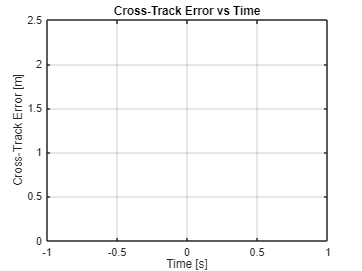


% Global time parameters
global dt DT;
dt = 0.001;   % integration time step
DT = 0.01;    % control update step
T = 60.0;     % max simulation time
time_vec = 0:DT:T;

% Vehicle & control parameters
L = 2.5;               % wheelbase
Ld = 2.0;              % look-ahead distance
gamma_max = deg2rad(45);
gamma_min = -gamma_max;
v_max = 1;
v_min = 0;

% State bounds
Qmax = [inf; inf; inf; gamma_max; v_max];
Qmin = [-inf; -inf; -inf; gamma_min; v_min];

% Initial state [x; y; theta; gamma; v]
q = [15; 5; pi/2; 0; 1];

% Generate circular path: radius 5m, center at (9,7)
a = 0:0.1:2*pi;
path = [9 + 5*sin(a)', 7 - 5*cos(a)'];

% Store results
q_trace = zeros(length(time_vec), 5);
cte_trace = zeros(length(time_vec), 1);

for k = 1:length(time_vec)
    % Control update
    [gamma_d, cte] = purePursuitController(q, L, Ld, path);
    u = [gamma_d; 1.0];  % desired steering angle, constant velocity
    
    % Propagate dynamics using your robot model
    q = robot_bike_dyn(q, u, [gamma_min; v_min], [gamma_max; v_max], Qmin, Qmax, L, 0.0, 0.0);

    % Store data
    q_trace(k, :) = q';
    cte_trace(k) = cte;
end

% === PLOTS ===

% Cross-track error over time
figure;
plot(time_vec, cte_trace, 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('Cross-Track Error [m]');
title('Cross-Track Error vs Time');
grid on;

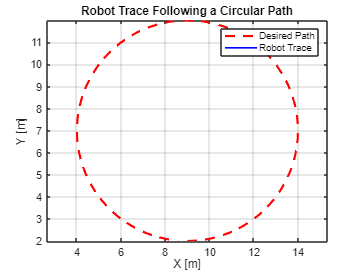


% Robot trace vs circular path
figure;
plot(path(:,1), path(:,2), 'r--', 'LineWidth', 2); hold on;
plot(q_trace(:,1), q_trace(:,2), 'b', 'LineWidth', 1.5);
xlabel('X [m]'); ylabel('Y [m]');
title('Robot Trace Following a Circular Path');
legend('Desired Path', 'Robot Trace');
axis equal;
grid on;